# PTT 爬蟲練習

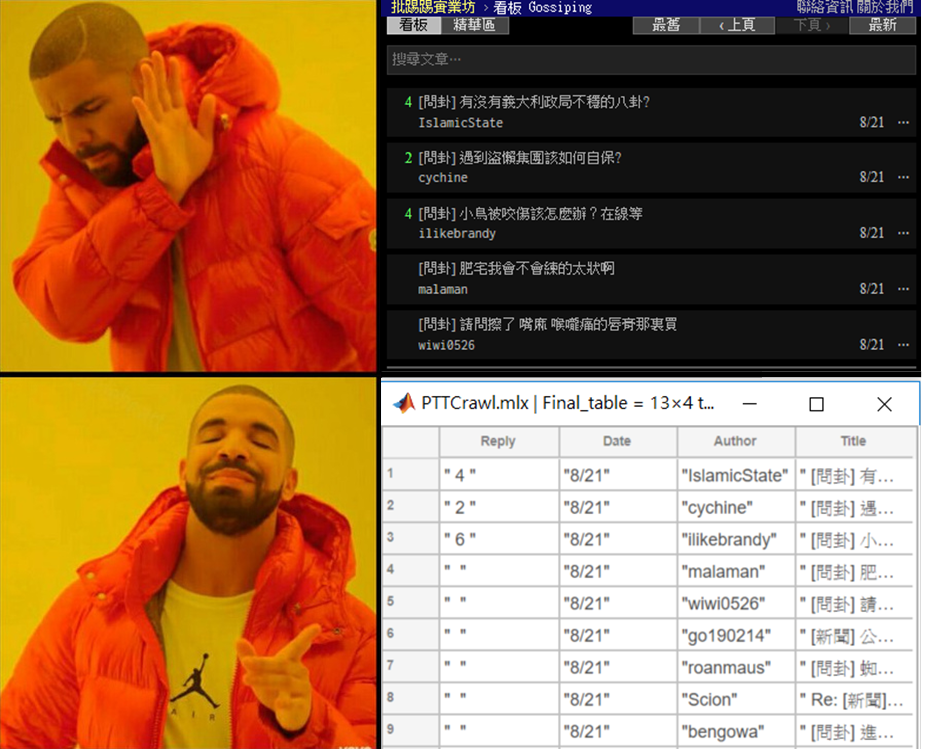

此練習程式碼用於爬取PTT版上文章資訊，文本分析工具箱的需求單純用來移除html tag

若是使用這不具備文本分析工具箱，可用一般文字處理手法移除

 ============================ 

#### 工具箱需求 Toolbox Requirement: 

- [文本分析工具箱 Text Analytics Toolbox] 

============================ 

#### 參數說明 : 

## 使用說明:

#### 無任何輸入

without_input = PTTCrawler

elapsedTime = 0.7458

without_input = 20×4 table
    Reply        Date           Author                        Title                  
    _____    _____________    ___________    ________________________________________

       3     2021年10月29日    -              "(本文已被刪除)[yonex1234]"               
       5     2021年10月29日    iamrw          "[問卦]七年級明明一堆除役了"                
      15     2021年10月29日    fawangching    "[問卦]98年退伍的義務役士官明年會被教召嗎？"   
     NaN     2021年10月29日    maxxxxxx       "Re:[問卦]大B哥根本沒打擊到館長啊"           
     NaN     2021年10月29日    lpbrother      "Re:[問卦]公投什麼題目比較好"               
       7     2021年10月29日    Willis5566     "[新聞]盼加強對台關係布達佩斯市長：匈牙利半"   
      39     2021年10月29日    fack3170       "[新聞]峮峮深夜淚眼道歉！「握棒方式」掀爭議"   
       2     2021年10月29日    soga0806       "[問卦]台灣比韓國早拿LOL世界冠軍，啊現在？"    
       2     2021年10月29日    cimo764        "[問卦]電子支付排名？"            

####  輸入查詢版

with_site = PTTCrawler('Tech_Job')

elapsedTime = 0.2406

with_site = 7×4 table
    Reply        Date           Author                       Title                
    _____    _____________    ___________    _____________________________________

     NaN     2021年10月29日    -              "(本文已被刪除)[woods301]"             
       1     2021年10月29日    burberry923    "[請益]亞獵士科技品管工程師"             
      22     2021年03月01日    mmkntust       "[公告]Tech_Job板板規2014.03.01"       
     NaN     2021年09月07日    mmkntust       "[公告]置底檢舉/推薦文章"               
       2     2021年03月02日    mmkntust       "[公告]如何消除退文轉自Ask板"            
       9     2021年02月14日    pzs            "[情報]律師為您解惑，免費勞動法問題諮詢服務"
      22     2021年03月31日    mmkntust       "[情報]薪資查詢平台"                    


with_site = PTTCrawler("Tech_Job")

elapsedTime = 0.1754

with_site = 7×4 table
    Reply        Date           Author                       Title                
    _____    _____________    ___________    _____________________________________

     NaN     2021年10月29日    -              "(本文已被刪除)[woods301]"             
       1     2021年10月29日    burberry923    "[請益]亞獵士科技品管工程師"             
      22     2021年03月01日    mmkntust       "[公告]Tech_Job板板規2014.03.01"       
     NaN     2021年09月07日    mmkntust       "[公告]置底檢舉/推薦文章"               
       2     2021年03月02日    mmkntust       "[公告]如何消除退文轉自Ask板"            
       9     2021年02月14日    pzs            "[情報]律師為您解惑，免費勞動法問題諮詢服務"
      22     2021年03月31日    mmkntust       "[情報]薪資查詢平台"                    


####  輸入查詢版與是否輸出檔案

with_siteNflag = PTTCrawler('Tech_Job',true)

elapsedTime = 0.2751

with_siteNflag = 7×4 table
    Reply        Date           Author                       Title                
    _____    _____________    ___________    _____________________________________

     NaN     2021年10月29日    -              "(本文已被刪除)[woods301]"             
       1     2021年10月29日    burberry923    "[請益]亞獵士科技品管工程師"             
      22     2021年03月01日    mmkntust       "[公告]Tech_Job板板規2014.03.01"       
     NaN     2021年09月07日    mmkntust       "[公告]置底檢舉/推薦文章"               
       2     2021年03月02日    mmkntust       "[公告]如何消除退文轉自Ask板"            
       9     2021年02月14日    pzs            "[情報]律師為您解惑，免費勞動法問題諮詢服務"
      22     2021年03月31日    mmkntust       "[情報]薪資查詢平台"                    


## **主函式**

function Data = PTTCrawler(site,genFile)
tic; % 使用 tic-toc 計算程式運行爬取時間
narginchk(0,3) % 檢查使用者輸入的變數數量是否符合
switch nargin
    case 0
        % 使用者沒有任何輸入，預設查詢八卦版
        site  = 'Gossiping';
        genFile = false;
        Data = StartCrawl(site,genFile);
    case 1
        % 使用者輸入欲查詢的板
        if isa(site,'string')
            site = char(site);
        end
        genFile = false;
        chkClass(site,genFile)
        Data = StartCrawl(site,genFile);
    case 2
        % 使用者輸入欲查詢的板並決定是否輸出檔案
        if isa(site,'string')
            site = char(site);
        end
        chkClass(site,genFile);
        Data = StartCrawl(site,genFile);
end

elapsedTime = toc
end

## Nested Function 架構

PTT 頁面爬取主程式

function Data = StartCrawl(site,genFile)

opt = weboptions('KeyName','cookie','KeyValue','over18=1'); %八卦版需要年齡驗證
url = ['https://www.ptt.cc/bbs/',site,'/index.html'];

% 使用 try-catch 來抓去網路連線可能發生的錯誤，並提供使用者錯誤訊息
try
    Ptt_raw = webread(url,opt);
catch status
    if strcmp(status.identifier,'MATLAB:webservices:UnknownHost')
        error('請檢查網路連線')
    elseif strcmp(status.identifier,'MATLAB:webservices:Timeout')
        error('連線時間過長')
    else
        error('未知錯誤')
    end
end

Data = cleanData;    % Output

if genFile
    filename = ['PTT爬取結果_',site,'.csv'];
    writetable(Data,filename)
end

% 將非結構性的爬蟲資料整理成 table 格式
    function Data = cleanData
        % 從 html 檔純文字中擷取資訊
        Title = regexp(Ptt_raw,'<?div class="title">.*?</div>?','match')';    % 文章標題
        Date = regexp(Ptt_raw,'<?div class="date">.*?</div>?','match')';    % 發表日期
        Author = regexp(Ptt_raw,'<?div class="author">.*?</div>?','match')';    % 發文者帳號
        Reply = regexp(Ptt_raw,'<?div class="nrec">.*?</div>?','match')';    % 回覆數量
        structTable = [Reply,Date,Author,Title];
        
        % ===== Text Analytics Toolbox Required ======
        cleanData = string(cellfun(@eraseTags,structTable,'UniformOutput',0)); % eraseTags: 刪除網頁標籤
        cleanData = regexprep(cleanData,'(\n|\t|\r| )','');
        
        Data = array2table(cleanData,'VariableNames',{'Reply','Date','Author','Title'});
        Data.Reply = str2double(Data.Reply);
        Data.Date = datetime(Data.Date,'InputFormat','MM/dd','Format','yyyy年MM月dd日');
        Data.Author = categorical(Data.Author);
    end
end

## SubFunction 架構

檢查使用者輸入的變數型態是否正確

function chkClass(title,genFile)
chktitle = isa(title,'char');
chkgenFile = isa(genFile,'logical');
if ~chktitle|~chkgenFile
    error('輸入格式錯誤')
end
end